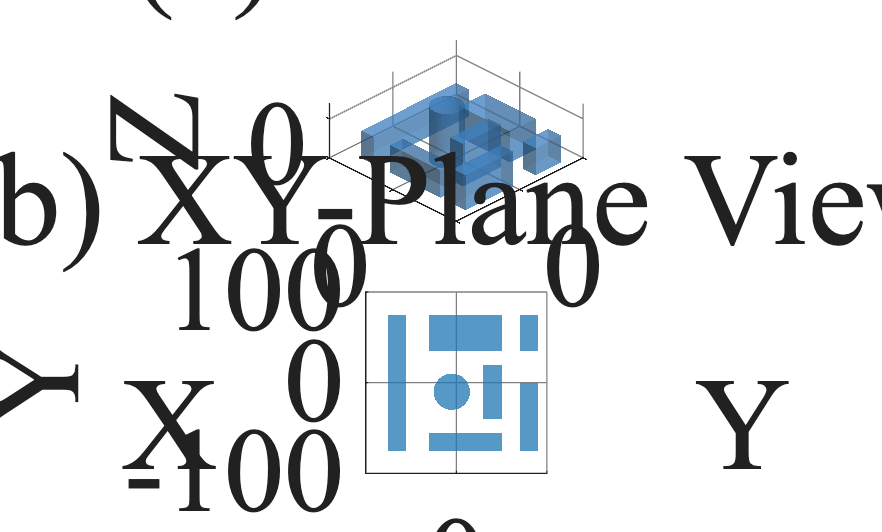

% 모든 STL 파일을 불러와 하나의 객체로 합치는 함수
function combined_mesh = combine_stls(file_names)
    combined_mesh.vertices = cell(1, length(file_names));
    combined_mesh.faces = cell(1, length(file_names));
    
    for i = 1:length(file_names)
        % stlread 함수를 사용하여 STL 파일을 읽고 triangulation 객체로 받음
        TR = stlread(file_names{i});
        
        % triangulation 객체에서 정점과 면 데이터를 추출
        combined_mesh.vertices{i} = TR.Points;
        combined_mesh.faces{i} = TR.ConnectivityList;
    end
end

% 저장 폴더 확인
if ~exist('./results','dir'); mkdir('./results'); end

% STL 파일 목록 (7개 파일 포함)
file_names = {'mesh0.stl', 'mesh1.stl', 'mesh2.stl', 'mesh3.stl', 'mesh4.stl', 'mesh5.stl', 'mesh6.stl'};

% 모든 STL 파일을 개별 메쉬로 결합
combined_mesh = combine_stls(file_names);
set(gcf, 'Color', 'w');                 % 배경 명시
set(gcf, 'InvertHardcopy', 'off');      % 저장 시 배경 유지

% 통일된 컬러와 알파값
object_color = [0.3216 0.6667 1];
object_alpha = 0.5;           % 알파값 (0: 완전 투명, 1: 불투명)
material([0.3 0.6 0.1 20 1]);

fs_title = 70; fs_label = 55; fs_tick = 45;

% 1. 3D 뷰
subplot(2, 1, 1);
hold on;
for i = 1:length(file_names)
    patch('Faces', combined_mesh.faces{i}, ...
          'Vertices', combined_mesh.vertices{i}, ...
          'FaceColor', object_color, ...
          'FaceAlpha', object_alpha, ...   % 반투명
          'EdgeColor', 'none', ...
          'FaceLighting', 'flat');
end
hold off;
axis equal;
xlim([-100, 100]); ylim([-100, 100]);
xlabel('X', 'FontName', 'Times New Roman', 'FontSize', fs_label);
ylabel('Y', 'FontName', 'Times New Roman', 'FontSize', fs_label);
zlabel('Z', 'FontName', 'Times New Roman', 'FontSize', fs_label);
title('(a) 3D View', 'FontName', 'Times New Roman', 'FontSize', fs_title);
set(gca, 'FontSize', fs_tick);
grid on;
set(gca, 'GridAlpha', 1);
set(gca, 'GridColor', [0.5 0.5 0.5]);
view(45, 30);
set(gca, 'FontName', 'Times New Roman', 'Color', 'none');
camlight('infinite');

% 2. X-Y 평면 뷰
object_color = [0.1216 0.4667 0.7059];
subplot(2, 1, 2);
hold on;
for i = 1:length(file_names)
    patch('Faces', combined_mesh.faces{i}, ...
          'Vertices', combined_mesh.vertices{i}, ...
          'FaceColor', object_color, ...
          'FaceAlpha', object_alpha, ...
          'EdgeColor', 'none');
end
hold off;
view(0, 90);
axis equal;
xlim([-100, 100]); ylim([-100, 100]);
xlabel('X', 'FontName', 'Times New Roman', 'FontSize', fs_label);
ylabel('Y', 'FontName', 'Times New Roman', 'FontSize', fs_label);
title('(b) XY-Plane View', 'FontName', 'Times New Roman', 'FontSize', fs_title);
set(gca, 'FontSize', fs_tick);
grid on;
set(gca, 'GridAlpha', 1);
set(gca, 'GridColor', [0.5 0.5 0.5]);
set(gca, 'FontName', 'Times New Roman', 'Color', 'none');
set(gcf, 'PaperUnits', 'inches', 'PaperPosition', [0 0 6 9]);

% Figure를 PNG, PDF 파일로 저장 (투명/조명 그대로)
print('./results/env_setup', '-dpng', '-r600');
print('./results/env_setup', '-dpdf', '-r600');

% ===== EPS 저장 전용: 투명/조명 OFF + painters 전환 =====
% ===== 대안: 조명 유지 + 고해상도 래스터 EPS =====
set(gcf,'Renderer','opengl');
print('./results/env_setup','-depsc','-opengl','-r600');